local_repository  = 'E:/ToxPathRaw/';
ToxFiles = dir([local_repository 'ToxDef/*.txt'])

ToxFiles = 34×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


normalFiles = dir([local_repository 'NormalDef/*.txt'])

normalFiles = 28×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


files = [ strcat('ToxDef/',{ToxFiles.name}) ...
          strcat('NormalDef/',{normalFiles.name})];
N = numel(files)   % total number of files

N = 62

type msbatchprocessing


function [MZ,Y] = msbatchprocessing(repository,files)
% MSBATCHPROCESSING Example function for BIODISTCOMPDEMO
%
% [MZ,Y] = MSBATCHPROCESSING(REPOSITORY,FILES) Preprocesses the
% spectrogram in files FILES and returns the mass/charge (MZ) and ion
% intensities (Y) vectors.
%
% Hard-coded parameters in the preprocessing steps have been adjusted to
% deal with the high-resolution spectrograms of the example.

% Copyright 2004-2013 The MathWorks, Inc.

K = numel(files);
Y = zeros(15000,K); % need to preset the size of Y for memory performance
MZ = zeros(15000,1);

parfor k = 1:K

    file = [repository files{k}]; 
    
    % read the two-column text file with mass-charge and intensity values
    fid = fopen(file,'r');
    ftext = textscan(fid, '%f%f');
    fclose(fid);
    signal = ftext{1};
    intensity = ftext{2};

    % resample the signal to 15000 points between 2000 and 11900
    mzout = (sqrt(2000)+(0:(15000-1))'*diff(sqrt([2000,11900]))/15000).^2;
    [mz,YR] = msresample(signal,

tic
repository = local_repository;
K = N; % change to N to do all

[toxMZ,toxY] = msbatchprocessing(repository,files(1:K));

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
> In interp1>Interp1DStripNaN (line 206)
> In interp1>Interp1DStripNaN (line 206)
  In interp1 (line 136)
  In msbackadj (line 296)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 46)
> In interp1>Interp1DStripNaN (line 206)
  In interp1 (line 136)
  In msbackadj (line 296)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 46)
  In interp1 (line 136)
  In msbackadj (line 296)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 46)


disp(sprintf('Sequential time for %d spectrograms: %f seconds',K,toc))

Sequential time for 62 spectrograms: 216.143496 seconds


toxY = msnorm(toxMZ,toxY,'QUANTILE',0.5,'LIMITS',[3500 11000],'MAX',50);
toxgrp = [repmat({'ToxDef'},size(ToxFiles));...
       repmat({'NormalDef'},size(normalFiles))];
ToxIdx = find(strcmp(toxgrp,'ToxDef'));
numel(ToxIdx) % number of files in the "ToxicDef" subdirectory

ans = 34

normalIdx = find(strcmp(toxgrp,'NormalDef'));
numel(normalIdx) % number of files in the "Normal" subdirectory

ans = 28

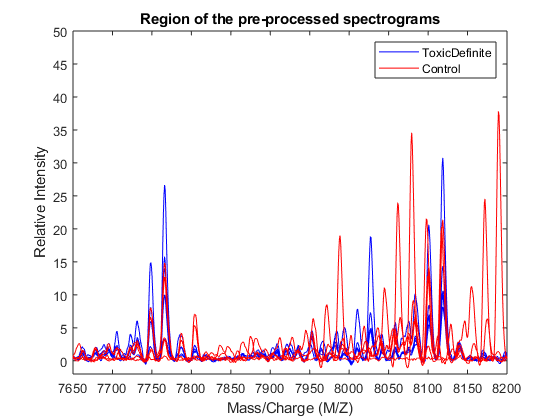

h = plot(toxMZ,toxY(:,ToxIdx(1:5)),'b',toxMZ,toxY(:,normalIdx(1:5)),'r');
axis([7650 8200 -2 50])
xlabel('Mass/Charge (M/Z)');ylabel('Relative Intensity')
legend(h([1 end]),{'ToxicDefinite','Control'})
title('Region of the pre-processed spectrograms')

save ToxicoQAQCdataset.mat toxY toxMZ toxgrp